syms t a mu x y real
s = [x;y];

assumeAlso(a > 0)
assumeAlso(mu > 0)
assumeAlso(mu < 1)

f_sym = [
    a - x + x^2*y
    mu - x^2*y
    ]

$$f\_sym = \left(\begin{array}{c} y\,x^{2}-x+a\\ \mu -x^{2}\,y \end{array}\right)$$

solve(f_sym,s)

ans = struct with fields:
    x: a + mu
    y: mu/(a^2 + 2*a*mu + mu^2)


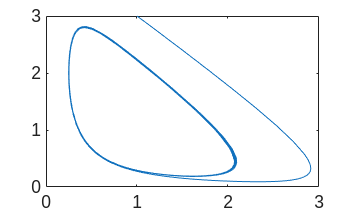

a = 1/8;
mu = 0.5;

f_ode = matlabFunction(subs(f_sym),'Vars',{t,s});

[tt,xx] = ode45(f_ode,[0 100],[1;3]);

plot(xx(:,1),xx(:,2))